addpath('C:\Users\sebas\Desktop\Sebastian\Universidad\5TO SEMESTRE\Métodos Númericos\rutinas_MN')


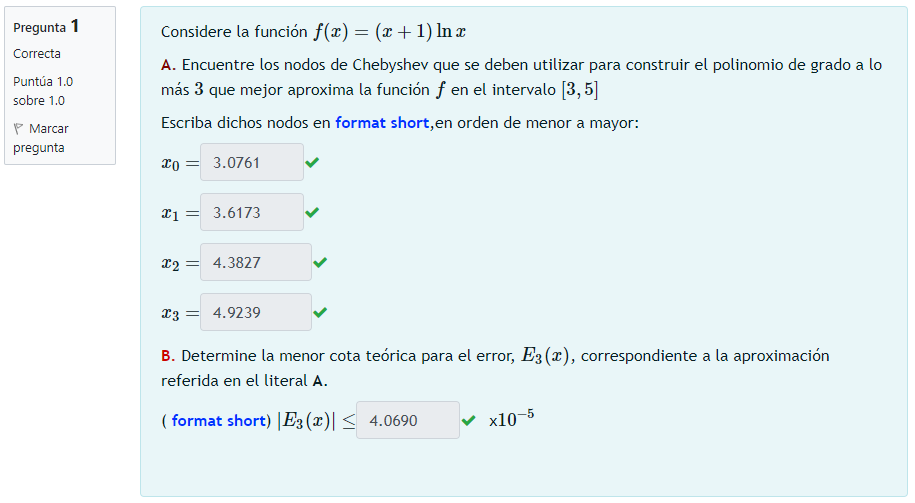

fun=@(x) (x+1).*log(x);
n=3;a=3,b=5;

a = 3

[X] = nodoschebyshev(fun, n, a, b)

X =     4.9239    4.3827    3.6173    3.0761


sort(X)

ans =     3.0761    3.6173    4.3827    4.9239


syms x;
df=diff(fun,x,n+1)

$$df = \frac{8}{x^{3}}-\frac{6\,\left(x+1\right)}{x^{4}}$$

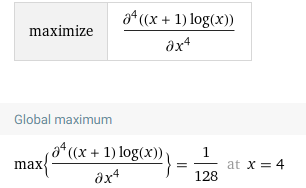

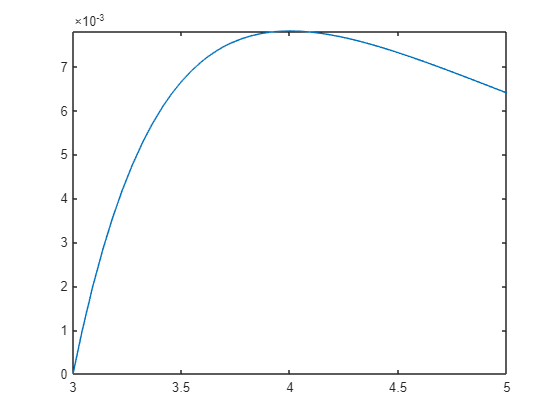

close all
fplot(abs(df))
xlim([3 5])

Cerror=double((2*(b-a)^(n+1))/(4^(n+1)*factorial(n+1))*subs(df, 'x', 4))

Cerror = 4.0690e-05

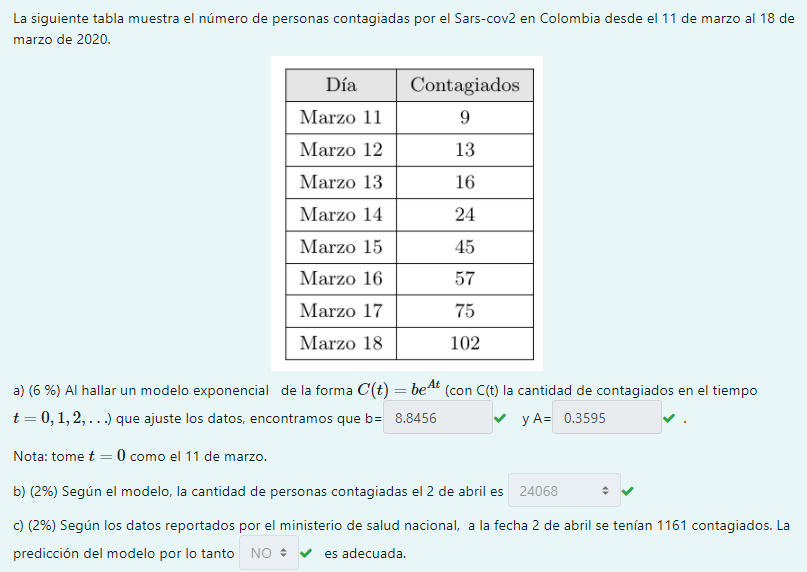

X=0:1:7;
Y=[9 13 16 24 45 57 75 102];
yn=log(Y)

yn =     2.1972    2.5649    2.7726    3.1781    3.8067    4.0431    4.3175    4.6250


[A, B] = lsline0 (X, yn);
a=A

a = 0.3595

b=exp(B)

b = 8.8456

plot(X,Y,'or')
hold on
f=@(x) b*exp(a*x)

f = function_handle with value:
    @(x)b*exp(a*x)


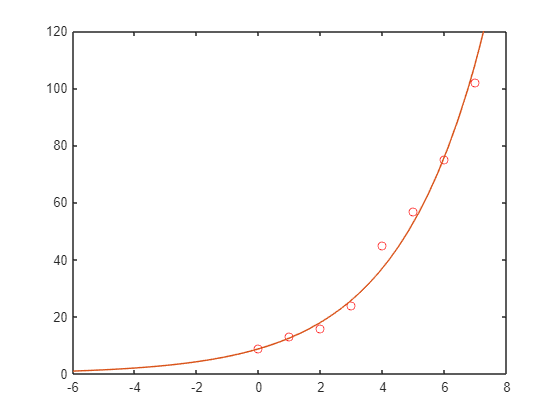

fplot(f)

f(22)

ans = 2.4068e+04

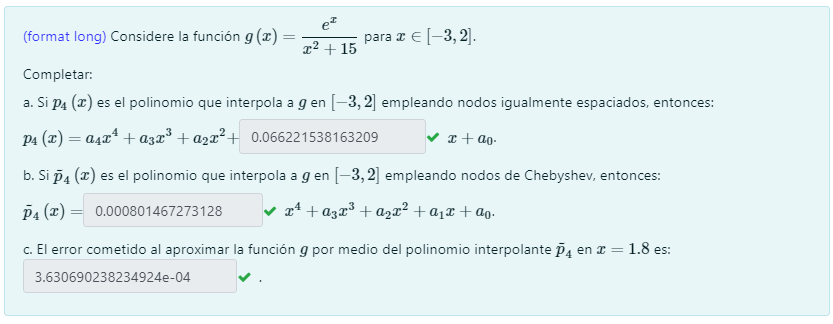

clear all
format long

f=@(x) exp(x)./(x.^2+15);
X1=linspace(-3,2,5)

X1 =   -3.000000000000000  -1.750000000000000  -0.500000000000000   0.750000000000000   2.000000000000000


Y1=f(X1)

Y1 =    0.002074461181994   0.009620702751582   0.039772502276238   0.136032129581537   0.388897689417403


[C] = newpoly (X1, Y1)

C =    0.000802062249376   0.007321473813972   0.029680399972051   0.066221538163209   0.066328226700991


n=4;a=-3;b=2;
[X, Y] = nodoschebyshev (f, n, a, b)

X =    1.877641290737884   0.969463130731183  -0.500000000000000  -1.969463130731183  -2.877641290737884


Y =    0.352921771184701   0.165404765972535   0.039772502276238   0.007390928295678   0.002416896232595


[C] = newpoly (X, Y)

C =    0.000801467273128   0.007310864798143   0.029626057009890   0.065984222793888   0.066221865815907


err=abs((polyval(C,1.8)-f(1.8)))

err =      3.630690238234924e-04


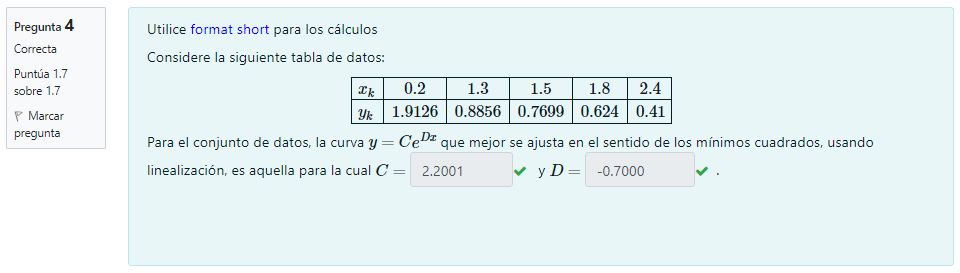

format short
X=[0.2 1.3 1.5 1.8 2.4];
Y=[1.9126 0.8856 0.7699 0.624 0.41];
yn=log(Y)

yn =     0.6485   -0.1215   -0.2615   -0.4716   -0.8916


[A, B] = lsline0 (X, yn);
a=A

a = -0.7000

b=exp(B)

b = 2.2001

close all
plot(X,Y,'or')
hold on
f=@(x) b*exp(a*x)

f = function_handle with value:
    @(x)b*exp(a*x)


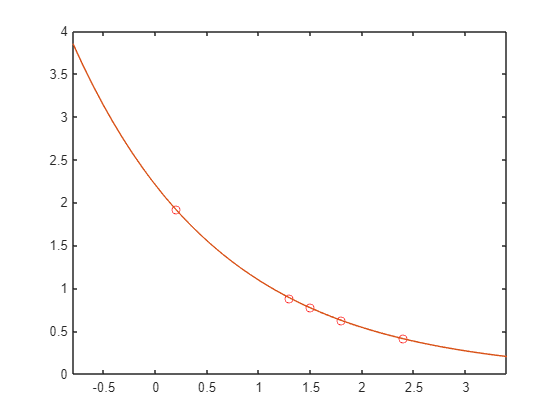

xlim([X(1)-1 X(5)+1])
fplot(f)

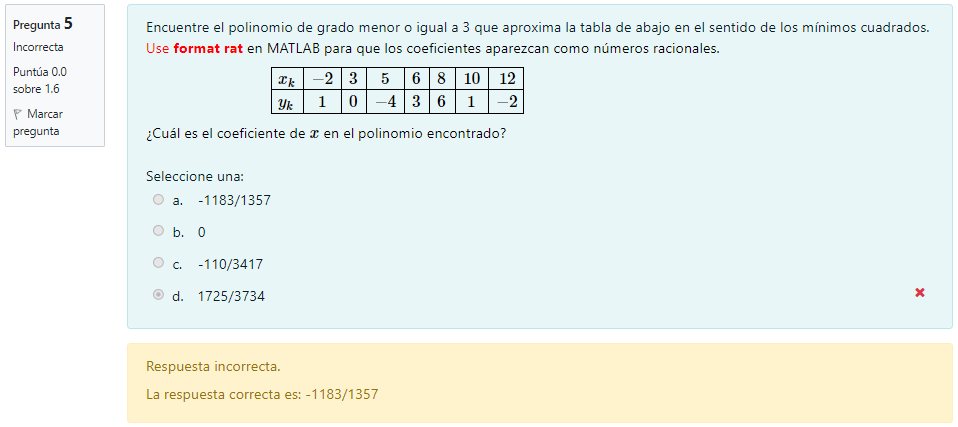

format rat
X=[-2 3 5 6 8 10 12]; Y=[1 0 -4 3 6 1 -2];M=3;
C = lspoly (X, Y, M);
C'

ans =     -110/3417      1725/3734     -1183/1357     -1493/551   


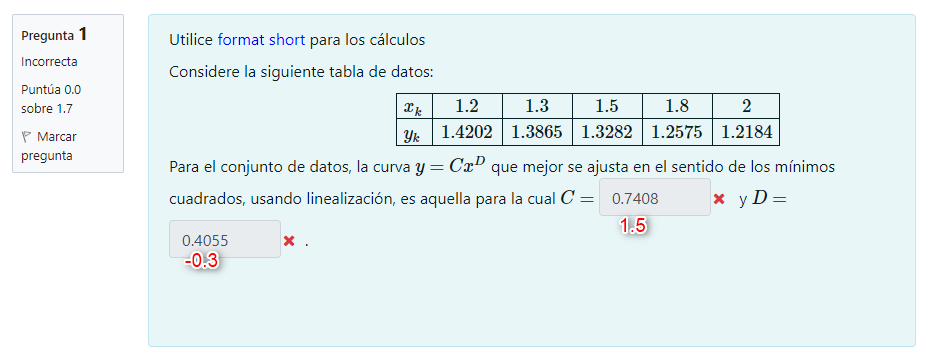

format short
X=[1.2 1.3 1.5 1.8 2];
Y=[1.4202 1.3865 1.3282 1.2575 1.2184];
xn=log(X)

xn =     0.1823    0.2624    0.4055    0.5878    0.6931


yn=log(Y)

yn =     0.3508    0.3268    0.2838    0.2291    0.1975


[A, B] = lsline0 (xn, yn)

A = -0.3000

B = 0.4055

C=exp(B)

C = 1.5000

D=A

D = -0.3000

close all
plot(X,Y,'or')
hold on
f=@(x) C*x^(D)

f = function_handle with value:
    @(x)C*x^(D)


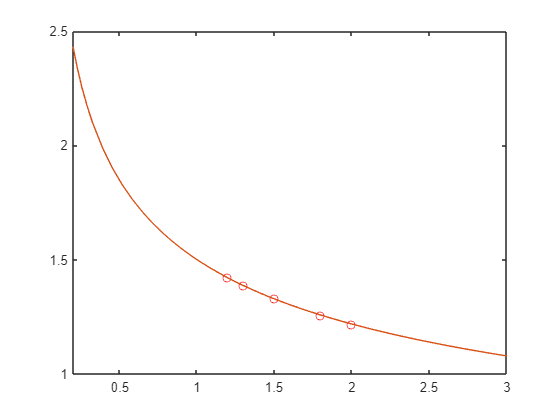

xlim([X(1)-1 X(5)+1])
fplot(f)

format rat
X=[-3 -2 -1 0 1 2 4 5 6]

X =       -3             -2             -1              0              1              2              4              5              6       


Y=[1/10 1/5 1/2 1 1/2 1/5 1/7 1/26 1/37]

Y =        1/10           1/5            1/2            1              1/2            1/5            1/7            1/26           1/37    


M=4;
C = lspoly (X, Y, M);
C'

ans =        5/14223       53/9678      -124/2103       -63/4717       674/1073  


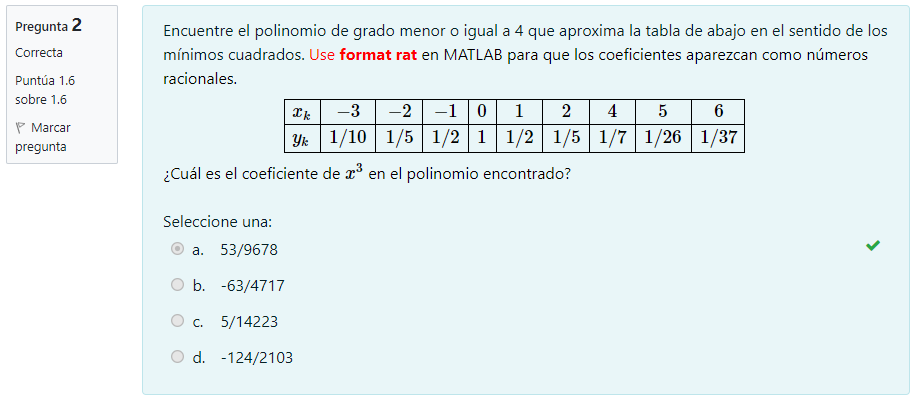

format short

f=@(x) x.^4 - exp(x); n=3; a=-2;b=2;
[X] = nodoschebyshev (f, n, a, b);
sort(X)

ans =    -1.8478   -0.7654    0.7654    1.8478


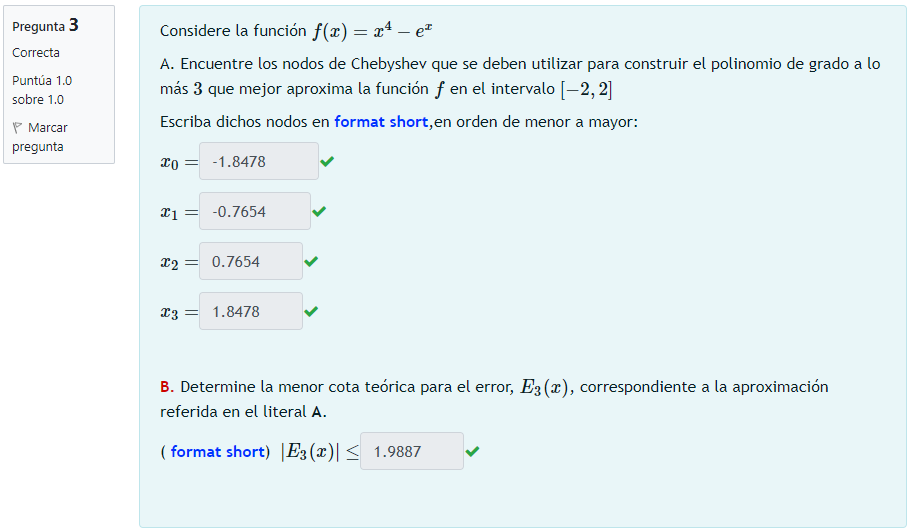

syms x;
df=diff(f,x,n+1)

$$df = 24-{\mathrm{e}}^{x}$$

close all
fplot(abs(df))
xlim([-2 2])
Cerror=double((2*(b-a)^(n+1))/(4^(n+1)*factorial(n+1))*subs(df, 'x', -2));

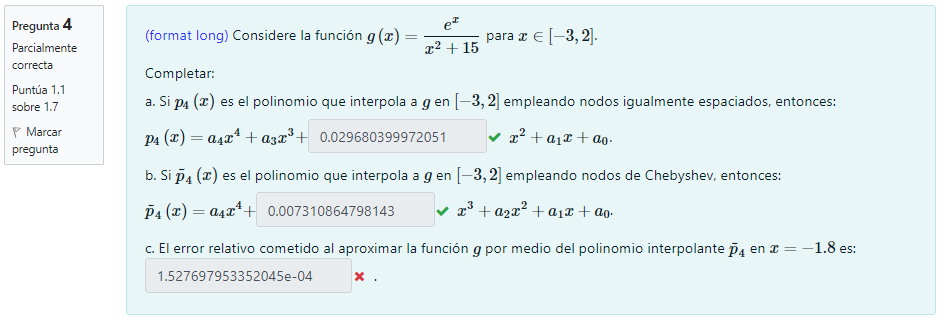

clear all
format long

f=@(x) exp(x)./(x.^2+15);
X1=linspace(-3,2,5)

X1 =   -3.000000000000000  -1.750000000000000  -0.500000000000000   0.750000000000000   2.000000000000000


Y1=f(X1)

Y1 =    0.002074461181994   0.009620702751582   0.039772502276238   0.136032129581537   0.388897689417403


[C] = newpoly (X1, Y1)

C =    0.000802062249376   0.007321473813972   0.029680399972051   0.066221538163209   0.066328226700991


n=4;a=-3;b=2;
[X, Y] = nodoschebyshev (f, n, a, b)

X =    1.877641290737884   0.969463130731183  -0.500000000000000  -1.969463130731183  -2.877641290737884


Y =    0.352921771184701   0.165404765972535   0.039772502276238   0.007390928295678   0.002416896232595


[C] = newpoly (X, Y)

C =    0.000801467273128   0.007310864798143   0.029626057009890   0.065984222793888   0.066221865815907


err=abs((polyval(C,-1.8)-f(-1.8))/f(-1.8))

err =    0.016857470106990


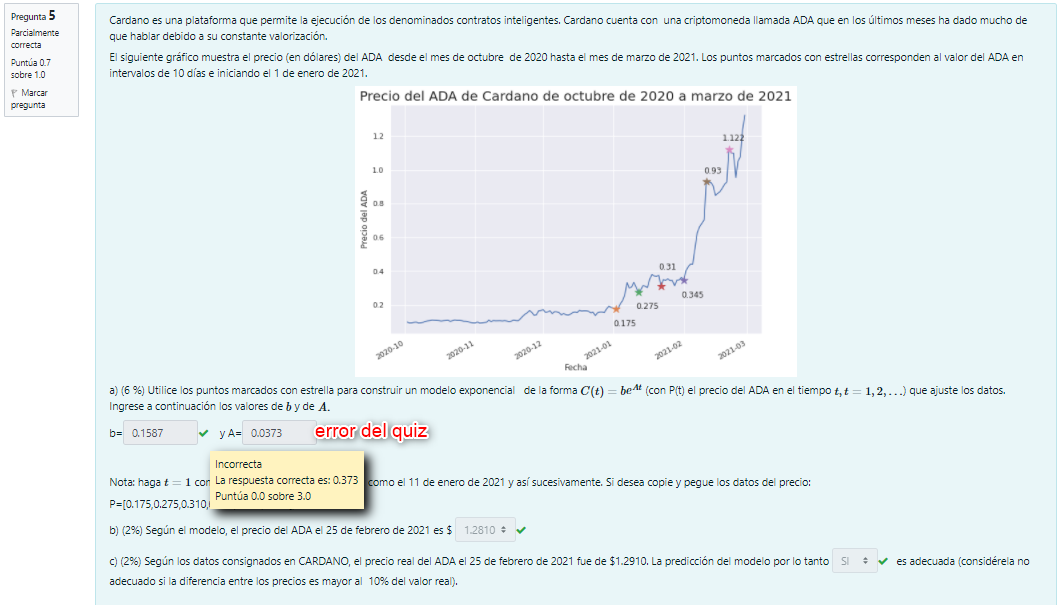

X=[1 11 21 31 41 51 ];
Y=[0.175 0.275 0.31 0.345 0.93 1.122];
yn=log(Y)

yn =   -1.742969305058623  -1.290984181315566  -1.171182981502945  -1.064210861950777  -0.072570692834835   0.115112807100505


[A, B] = lsline0 (X, yn);
b=exp(B)

b =    0.158697145832956


a=A

a =    0.037293208987971


close all
plot(X,Y,'or')
hold on
f=@(x) b*exp(a*x)

f = function_handle with value:
    @(x)b*exp(a*x)


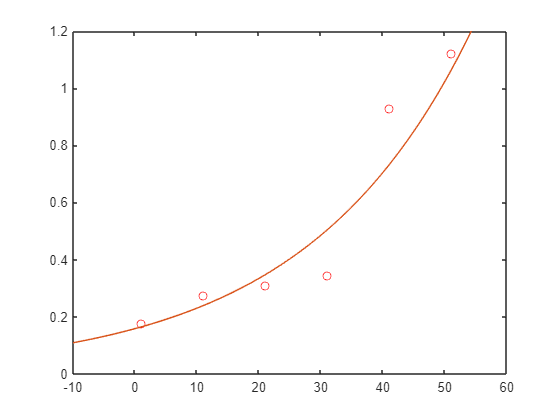

fplot(f)

f(31+25)

ans =    1.281026957815255


(1.2910-1.2810)

ans =    0.010000000000000


1.2910*.1

ans =    0.129100000000000


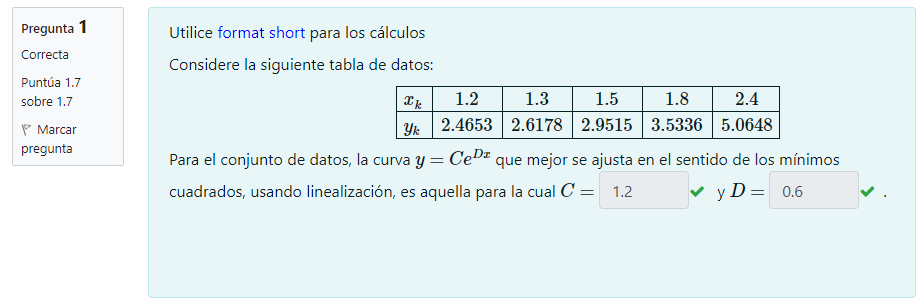

format short
X=[1.2 1.3 1.5 1.8 2.4  ];
Y=[2.4653 2.6178 2.9515 3.5336 5.0648];
yn=log(Y)

yn =     0.9023    0.9623    1.0823    1.2623    1.6223


[A, B] = lsline0 (X, yn);
C=exp(B)

C = 1.2000

D=A

D = 0.6000

close all
plot(X,Y,'or')
hold on
f=@(x) C*exp(D*x)

f = function_handle with value:
    @(x)C*exp(D*x)


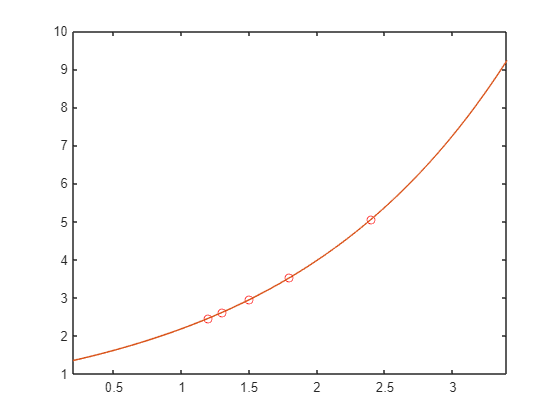

xlim([X(1)-1 X(5)+1])
fplot(f)

X=[10 15 20 25 40 50 55 60];
Y=[4 20 18 50 33 48 80 60];
[A, B] = lsline0 (X, Y)

A = 1.1101

B = 0.9642

A*30+B

ans = 34.2682

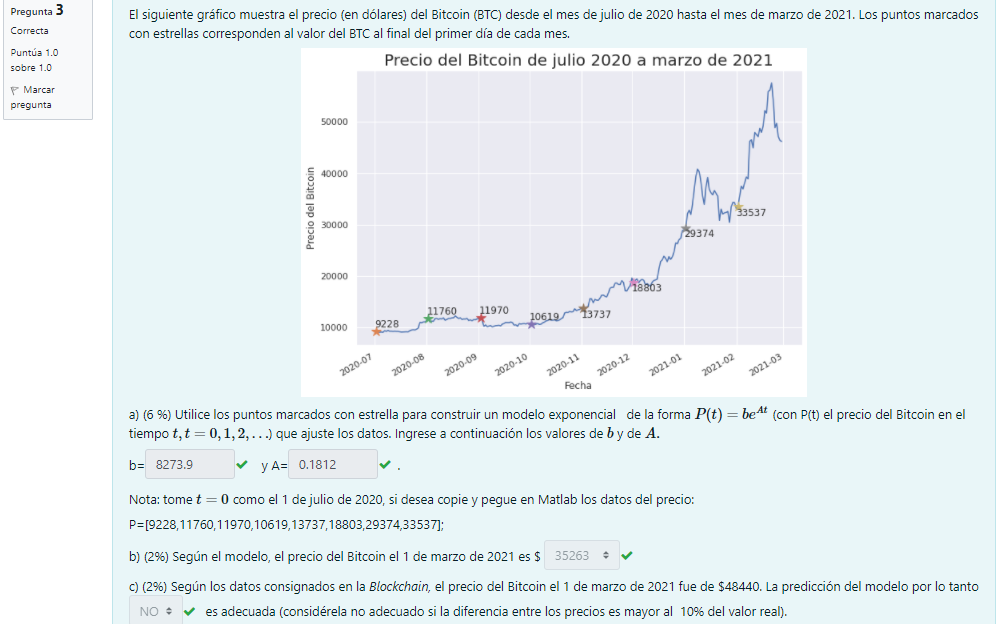

X=0:1:7;
Y=[9228 11760 11970 10619 13737 18803 29374 33537];
yn=log(Y)

yn =     9.1300    9.3725    9.3902    9.2704    9.5278    9.8418   10.2879   10.4204


[A, B] = lsline0 (X, yn);
b=exp(B)

b = 8.2739e+03

a=A

a = 0.1812

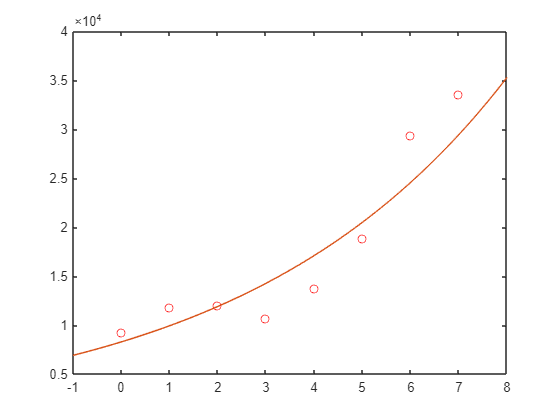

close all
plot(X,Y,'or')
hold on
f=@(x) b*exp(a*x);
xlim([X(1)-1 X(8)+1])
fplot(f)

f(8)

ans = 3.5263e+04

48440*.1

ans = 4844

48440-f(8)

ans = 1.3177e+04

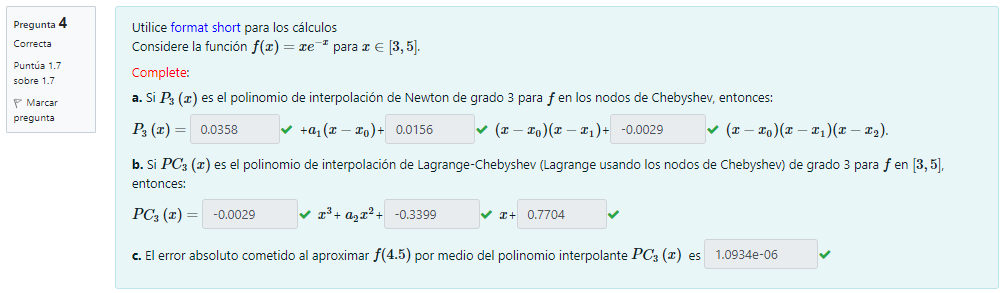

f=@(x) x.*exp(-x);
n=3;a=3;b=5;
[X, Y] = nodoschebyshev (f, n, a, b);
[C, D] = newpoly (X, Y)

C =    -0.0029    0.0530   -0.3399    0.7704


D =     0.0358         0         0         0
    0.0547   -0.0350         0         0
    0.0971   -0.0554    0.0156         0
    0.1419   -0.0828    0.0209   -0.0029



[C] = lagran (X, Y)

C =    -0.0029    0.0530   -0.3399    0.7704


err=abs((polyval(C,4.5)-f(4.5)))

err = 1.0934e-06

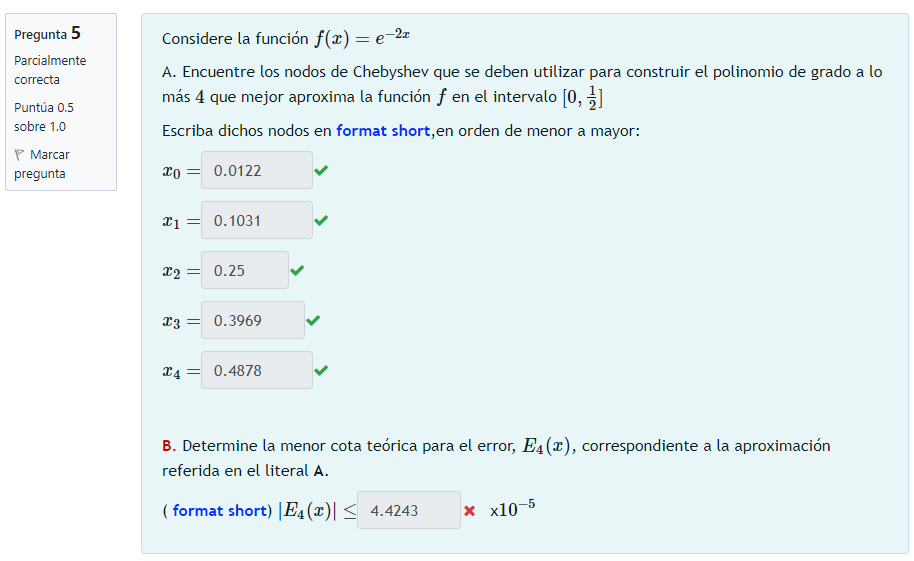

f=@(x)exp(-2.*x);n=4;a=0;b=1/2;
[X, Y] = nodoschebyshev(f, n, a, b);    
sort(X)

ans =     0.0122    0.1031    0.2500    0.3969    0.4878


syms x;
df=diff(f,x,n+1)

$$df = -32\,{\mathrm{e}}^{-2\,x}$$

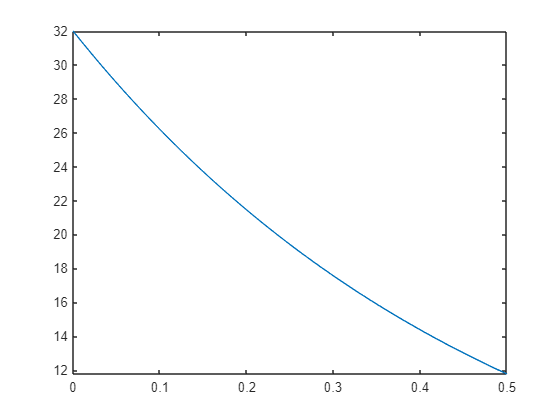

close all
fplot(abs(df))
xlim([a b])

(2*(b-a)^(n+1))/(4^(n+1)*factorial(n+1))*32*exp(2*(0))

ans = 1.6276e-05

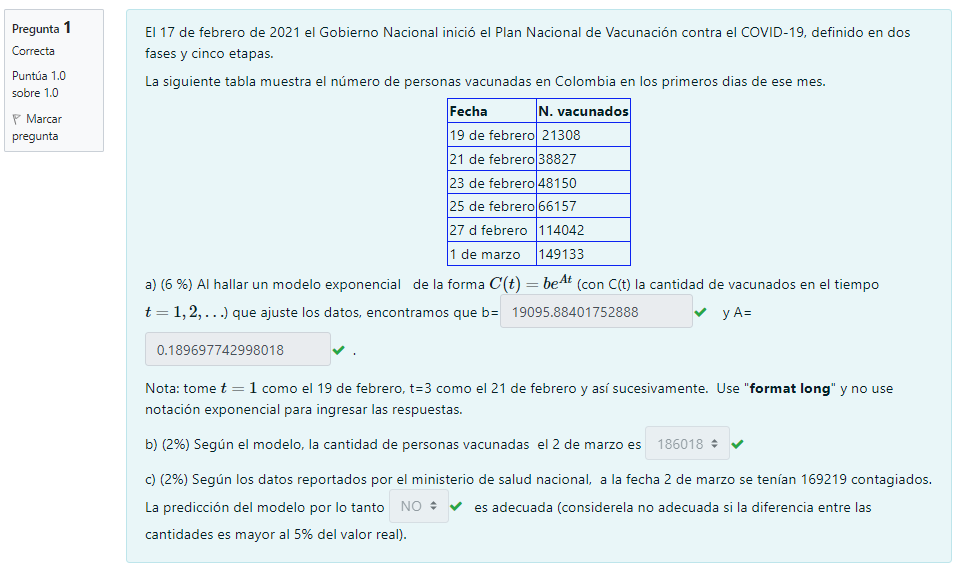

X=[1 3 5 7 9 11];Y=[21308 38827 48150 66157 114042 149133];
format long
yn=log(Y)

yn =    9.966837868036890  10.566871159890386  10.782076417226271  11.099785984050369  11.644322080578892  11.912593804231216


[A, B] = lsline0 (X, yn);
b=exp(B)

b =      1.909588401752888e+04


a=A

a =    0.189697742998018


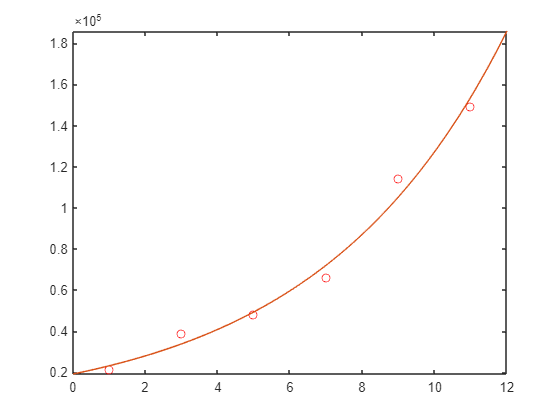

close all
plot(X,Y,'or')
hold on
f=@(x) b*exp(a*x);
xlim([X(1)-1 X(length(X))+1])
fplot(f)

f(12)

ans =      1.860184256314745e+05


169219*.05

ans =      8.460950000000001e+03


f(12)-169219

ans =      1.679942563147447e+04


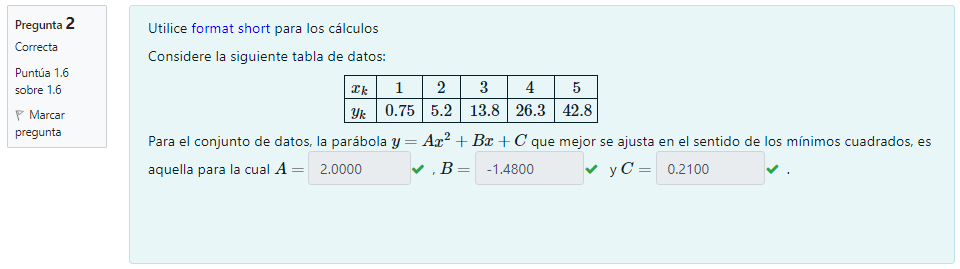

format short
X=1:1:5;Y=[.75 5.2 13.8 26.3 42.8];M=2;
C = lspoly (X, Y, M);
C'

ans =     2.0000   -1.4800    0.2100


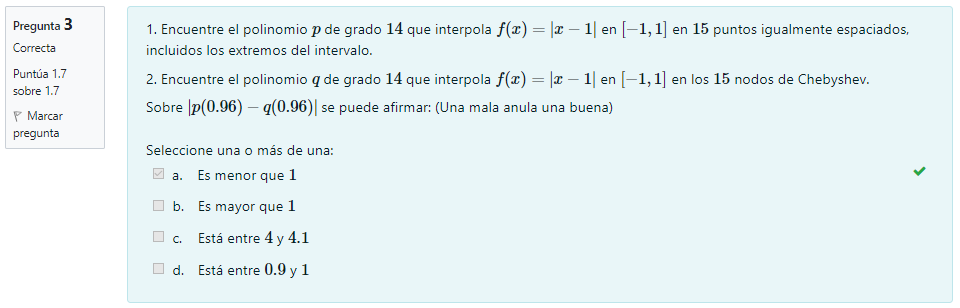

f=@(x) abs(x-1);
X1=linspace(-1,1,15);Y1=f(X1); 
[p] = newpoly (X1, Y1)

p =     0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -1.0000    1.0000


n=14;a=-1;b=1;
[X, Y] = nodoschebyshev (f, n, a, b);
[q] = newpoly (X, Y)

q =    -0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000    0.0000   -0.0000   -0.0000    0.0000   -1.0000    1.0000


abs(polyval(p,0.96)-polyval(q,0.96))

ans = 2.5535e-15

PREGUNTA 1 QUIZ 2

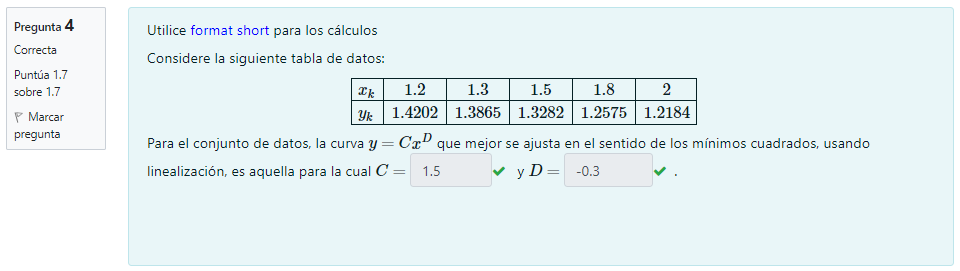

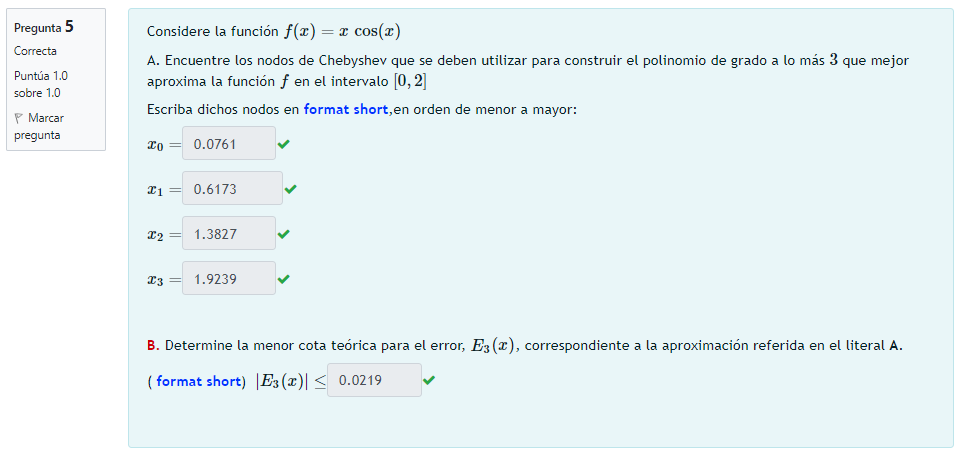

f=@(x) x.*cos(x);
n=3;a=0;b=2;
[X, Y] = nodoschebyshev (f, n, a, b);
sort(X)

ans =     0.0761    0.6173    1.3827    1.9239


syms x;
df=diff(f,x,n+1)

$$df = 4\,\sin\left(x\right)+x\,\cos\left(x\right)$$

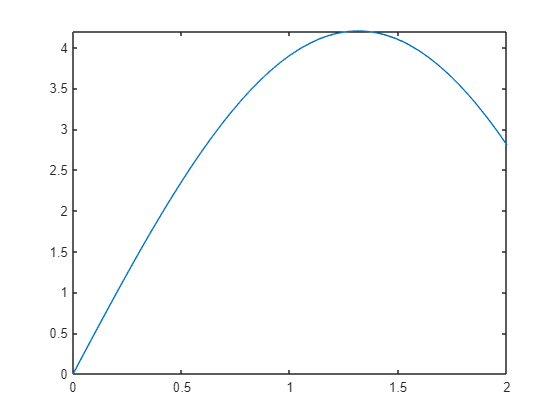

close all
fplot(abs(df))
xlim([0 2])

Cerror=double((2*(b-a)^(n+1))/(4^(n+1)*factorial(n+1))*subs(df, 'x', 1.31383771649289832398132358419295329475))

Cerror = 0.0219